# PRACTICA 2: REALIZAR UN GRABADORA.

#### Objetivo: Realizar un grabador de audio que permita guardar dos audios distintos uno que tenga mas duracion que el secundario.

Requisitos:

1.- el usuario puede seleccionar las siguientes opciones:

- Grabar un audio principal que sea el audio mas grande que el audio secundario.

- Grabar un audio secundario que sea menor al audio principal (duracion de 3 segundos maximo).

2.- Se podra modificar el audio principal colocando el audio secundario en donde el usuario desee (habra una leyenda recomendando al usuario colocar el audio secundario en espacios de silencio).

3.-  El usuario visualizara la onda de audio resultante una vez modificado el audio.

4.- Se podra guardar el audio resultante en un archivo .WAV 

# Practica 2.1: MODIFICAR LAS ONDAS PARA CREAR UN MENSAJE SUBBLIMINAL EN El AUDIO.

#### Objetivo: Combinar la onda principal con la onda secundaria. La onda principal seguira teniendo su forma original, mientras que la onda secundaria se volteara para colocarlo al reves y solo se pueda escuchar el audio secundario escuchando el audio resultante al reves.

## Comienzo del codigo

**1. Principio del programa:** para comenzar con el codigo, lo mas importante es realizar la limpieza general de las variables, pestañas y datos previamente cargados, de esta forma, no obtendremos errores 

una vez limpio todo lo necesario, podemos continuar con la definicion de otros conceptos.

**2. Implementacion del menu: **despues creamos un menu que permita seleccionar las opciones de grabar el audio principal, grabar el audio secundario, crear el audio resultante, crear el mensaje subliminal, guardar el audio resultante y salir del programa.

**3. Creacion de funciones: **implementamos funciones de usuario donde, recibimos el audio principal, recibimos el audio secundario, combinamos los audios para crear el audio subliminar, escuchamos el audio al original, escuchamos el audio al reves para oir el audio subliminal y guardamos el audio al reves.

# IMPLEMENTACION DEL CODIGO FINAL

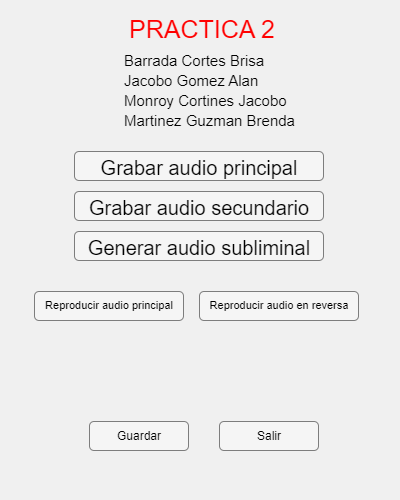

%Principio del programa para limpiar 
%todo lo que tengo registro
clear
close all
clc

%funcion de usuario de el menu de ondas
    % Crear la ventana de la interfaz gráfica
    fig = uifigure('Name', 'PRACTICA 2: GRABADORA DE MENSAJES SUBLIMINALES', 'Position', [900 200 400 500]);
    
        
    %COLOCACION DE NOMBRES Y PRACTICA
    uilabel(fig,'Text', 'PRACTICA 2', 'Position',[130 460 150 30],'FontSize',25,'FontColor','r');
    uilabel(fig,'Text', 'Barrada Cortes Brisa', 'Position', [125 430 150 20],'FontSize',15);
    uilabel(fig,'Text', 'Jacobo Gomez Alan', 'Position', [125 410 150 20],'FontSize',15);
    uilabel(fig,'Text', 'Monroy Cortines Jacobo', 'Position', [125 390 200 20],'FontSize',15);
    uilabel(fig,'Text', 'Martinez Guzman Brenda', 'Position', [125 370 180 20],'FontSize',15);
    
    %Creamos un boton para grabar el audio principal, el cual es donde
    %ingresaremos nuestro audio subliminal
    %este boton nos lleva a la funcion para grabar y guardar nuestro audio
    btnAudio1 = uibutton(fig, 'Text', 'Grabar audio principal', 'Position', [75 320 250 30], ...
                         'ButtonPushedFcn', @(btn, event) grabaraudio1(),'FontSize',20);
    %Creamos un boton para grabar el audio principal, el cual insertamos en
    %el audio principal
    %este boton nos lleva a la funcion para grabar y guardar nuestro audio
    btnAudio2 = uibutton(fig, 'Text', 'Grabar audio secundario', 'Position', [75 280 250 30], ...
                         'ButtonPushedFcn', @(btn, event) grabaraudio2(),'FontSize',20); 
    %Este boton nos lleva a la funcion para generar nuestro audio final
    %subliminal
    btnGenAud = uibutton(fig, 'Text', 'Generar audio subliminal', 'Position', [75 240 250 30], ...
                         'ButtonPushedFcn', @(btn, event) generaraudio(),'FontSize',20);
    %Este boton nos lleva a la funcion para escuchar nuestro audio ya con
    %el mensaje subliminal implementado
    btnRepAud1 = uibutton(fig, 'Text', 'Reproducir audio principal', 'Position', [35 180 150 30], ...
                         'ButtonPushedFcn', @(btn, event) reproduciraudio(),'FontSize',11);
    %Este boton nos lleva a la funcion para escuchar nuestro audio ya con
    %el mensaje subliminal implementado pero con este se escucha el audio
    %subliminal
    btnRepFinal = uibutton(fig, 'Text', 'Reproducir audio en reversa', 'Position', [200 180 160 30], ...
                         'ButtonPushedFcn', @(btn, event) reproducirreversa(),'FontSize',11);

    %Este boton nos lleva a la funcion para guardar los audios, pero solo
    %es un boton señuelo, puesto que solo salta un mensaje de guardado ya
    %que siempre se guardan los audios
    uibutton(fig, 'Text', 'Guardar', 'Position', [90 50 100 30], 'ButtonPushedFcn', @(btn, event) guardar());

    
    % Botón de Salir
    %este botton es para salir del programa
    uibutton(fig, 'Text', 'Salir', 'Position', [220 50 100 30], 'ButtonPushedFcn', @(btn, event) close(fig));

%Esta es la funcion que nos hace grabar el audio principal para integrarle
%el mensaje subliminal
function grabaraudio1()  
    %aqui solo es texto y generacion de la interfaz
    aud = uifigure('Name', 'Grabar audio principal', 'Position', [400 300 1200 600]);
    panel = uipanel(aud,'Position',[50 80 1100 400]);
    uilabel(panel,'Text', 'Audio principal requiere minimo 10 seg, sino se coloca menos de 10 seg por default grabara 10 seg', 'Position',[100 70 1000 40],'FontSize',20);
    uilabel(panel,'Text', 'Cuanto tiempo desea grabar            seg', 'Position',[350 40 600 40],'FontSize',20);
    inputTiempo = uieditfield(panel, 'numeric', 'Position', [610 50 50 20]);
    
    %Este pedazo genera la grafica para ver la onda de audio dentro de la
    %figura (Interfaz) sin necesidad de generar otra interfaz para ver la
    %onda
    ax1 = uiaxes(panel,'Position',[50 120 1000 200]);
    title(ax1, "Onda de audio grabada");
    xlabel(ax1, "Tiempo(seg)");
    ylabel(ax1, "Amplitud");

    %este if evalua que el usuario ingrese mas de 10 segundos ya que el
    %audio subliminal solo durara 3 segundos
    if inputTiempo.Value <= 10
        time = 10;
    else
        time = inputTiempo.Value;
    end
    
    %boton de guardar que nos guarda el audio y muestra la grafica
    %resultante del audio grabado
    uibutton(aud, 'Text', 'Grabar', 'Position', [100 100 100 30],'ButtonPushedFcn', @(btn, event) recibirgrafica1(time, ax1),'FontSize',20);
    % Botón de Salir
    %este botton es para salir solo de la interfaz
    uibutton(aud, 'Text', 'Salir', 'Position', [1000 100 100 30],'ButtonPushedFcn', @(btn, event) close(aud),'FontSize',20);
end

%esta funcion guarda el audio en .wav y manda a graficar el audio
%pero esta solo sirve para el audio principal
function recibirgrafica1(time, ax)
    fs = 44100;
    au1 = GraficarAudio(time, ax);
    audiowrite('AudioPrincipal.wav', au1, fs);
end

%Esta es la funcion que nos hace grabar el audio subliminal para integrarlo
%en el audio principal
function grabaraudio2()
    %aqui solo es texto y generacion de la interfaz
    aud = uifigure('Name', 'Grabar audio subliminal', 'Position', [400 300 1200 600]);
    panel = uipanel(aud,'Position',[50 80 1100 400]);
    
    %Este pedazo genera la grafica para ver la onda de audio dentro de la
    %figura (Interfaz) sin necesidad de generar otra interfaz para ver la
    %onda    
    ax2 = uiaxes(panel,'Position',[50 120 1000 200]);
    title(ax2, "Onda de audio grabada");
    xlabel(ax2, "Tiempo(seg)");
    ylabel(ax2, "Amplitud");

    %boton de guardar que nos guarda el audio y muestra la grafica
    %resultante del audio grabado
    uibutton(aud, 'Text', 'Grabar', 'Position', [100 100 100 30], 'ButtonPushedFcn', @(btn, event) recibirgrafica2(3, ax2),'FontSize',20);
    % Botón de Salir
    %este botton es para salir solo de la interfaz
    uibutton(aud, 'Text', 'Salir', 'Position', [1000 100 100 30],'ButtonPushedFcn', @(btn, event) close(aud),'FontSize',20);
end

%esta funcion guarda el audio en .wav y manda a graficar el audio
%pero esta solo sirve para el mensaje subliminal
function recibirgrafica2(time, ax)
    fs = 44100;
    au2 = GraficarAudio(time, ax);
    audiowrite('MensajeSubliminal.wav', au2, fs);
end

%Esta funcion ya hace la grafica para poder vizualizarla
function audioData = GraficarAudio(time, ax)
    audioData = Grabar(time);
    t = linspace(0, time, length(audioData));
    plot(ax, t, audioData);
end

%Esta funcion Graba el audio y rescata los valores en el eje y, osea los
%valores de la grafica en si para poder usarlas para graficar
function audioData = Grabar(t)
    fs = 44100; %frecuencia de mouestreo
    recObj = audiorecorder(fs, 16, 1); %recupera el audio grabado con la frecuencia de muestreo, 16 bits y un canal
    recordblocking(recObj, t); 
    audioData = getaudiodata(recObj); %obtiene los valores del audio en el eje y
    sound(audioData, fs); %reproduce el sonido
end
    
    
%esta funcion ya hace que puedas generar el audio con el mensaje
%subliminal, te deja vizualizar las ondas de los audios para que puedas
%escojer en que tiempo colocaras el mensaje subliminal
function generaraudio()
    %aqui solo es texto y generacion de la interfaz
    figuraCombinar = uifigure('Name', 'CREAR AUDIO SUBLIMINAL', 'Position', [400 300 1200 600]);
    uilabel(figuraCombinar,'Text', 'Coloque donde quiere poner el Audio subliminal.', 'Position',[350 550 600 30],'FontSize',25,'FontColor','r');
    uilabel(figuraCombinar,'Text', 'Coloque el segundo Audio Grabado en algun espacio con silencio (sin ruido)', 'Position', [370 520 600 30],'FontSize',15);

    %LEER LOS AUDIOS
    [au1,fs] = audioread("AudioPrincipal.wav");
    [au2,fs] = audioread("MensajeSubliminal.wav");

    %aqui Generamos el eje x a partir de la longitud de la onda de los
    %audios dividiendo, osea separando su frecuencia de muestreo, dejando
    %solo el tiempo que dura el audio
    t1 = linspace(0, length(au1)/fs, length(au1));
    t2 = linspace(0, length(au2)/fs, length(au2));
    %las muestras seran la longitud total de la onda del audio

    %aqui solo es texto y generacion de un panel para ver las ondas
    panel = uipanel(figuraCombinar, 'Position', [50 80 1100 400]);
    uilabel(panel,'Text', 'Coloque en que segundo quiere colocar el mensaje:', 'Position',[250 05 600 40],'FontSize',20);
    
    %Este pedazo genera la grafica para ver la onda de audio dentro de la
    %figura (Interfaz) sin necesidad de generar otra interfaz para ver la
    %onda, pero este pertenece al audio principal
    ax1 = uiaxes(panel, 'Position', [50 220 1000 150]);
    title(ax1, 'Audio Principal');
    xlabel(ax1, 'Tiempo (segundos)');
    ylabel(ax1, 'Amplitud');
    plot(ax1,t1,au1);

    %del mismo modo aqui pero para el mensaje subliminal
    ax2 = uiaxes(panel, 'Position', [50 50 1000 150]);
    title(ax2, 'Mensaje Subliminal');
    xlabel(ax2, 'Tiempo (segundos)');
    ylabel(ax2, 'Amplitud');
    plot(ax2,t2,au2);

    %aqui creo un mensaje label que se modifica 
    mensajeLabel = uilabel(figuraCombinar, 'Text', '', 'Position', [400 25 400 30], 'FontSize', 25);
    inputTempo = uieditfield(panel, 'numeric', 'Position', [715 15 50 20]);
    %mandamos el tiempo donde el usario quiere ingresar el mensaje
    %subliminal
    %boton para guardar el audio generadom, nos manda a la funcion que
    %genera el audio final o resultante
    uibutton(figuraCombinar, 'Text', 'Guardar', 'Position', [250 20 100 30], 'ButtonPushedFcn', @(btn, event) evaluar(inputTempo, au1, au2, fs));
        
    %aqui evaluamos que el tiempo que ingrese el usuario sea correcto y no
    %ingrese digitos fuera del rango
    function evaluar(inputTempo, au1, au2, fs)
        if inputTempo.Value < 0 || isnan(inputTempo.Value) || inputTempo.Value > length(au1)/fs 
            mensajeLabel.Text = 'ERROR: Valor ingresado inválido';
        else
            mensajeLabel.Text = 'Valor asignado correctamente';
            tiempoasign = inputTempo.Value;
            CrearaudioSub(tiempoasign, au1, au2, fs)
        end
    end
    % Botón de Salir
    %este botton es para salir solo de la interfaz
    uibutton(figuraCombinar, 'Text', 'Salir', 'Position', [850 20 100 30], 'ButtonPushedFcn', @(btn, event) close(figuraCombinar));
end


function CrearaudioSub(tiempoasign, au1, au2, fs) 
    AudioInv = flipud(au2); % Invierte el audio
    AudioInv = 0.05 * AudioInv; % Atenúa el volumen

    AudioOculto = au1;
    Pos_ins = round(tiempoasign * fs); % Calcula la posición de inserción

    % Asegurar que la posición de inserción no exceda los límites
    if Pos_ins + length(AudioInv) - 1 > length(AudioOculto)
        error('ERROR: La inserción excede la duración del audio original.');
    end

    % Insertar el audio invertido
    AudioOculto(Pos_ins : Pos_ins + length(AudioInv) - 1) = ...
        AudioOculto(Pos_ins : Pos_ins + length(AudioInv) - 1) + AudioInv;

    % Guardar el audio final
    audiowrite('AudioFinal.wav', AudioOculto, fs);
end

function reproduciraudio()
    aud = uifigure('Name', 'Audio Final Grabado', 'Position', [400 300 1200 600]);
    panel = uipanel(aud,'Position',[50 80 1100 400]);
    
    [auf,fs] = audioread("AudioFinal.wav");
    tf = linspace(0, length(auf)/fs, length(auf));

    aux = uiaxes(panel,'Position',[50 120 1000 200]);
    title(aux, "Onda de Final");
    xlabel(aux, "Tiempo(seg)");
    ylabel(aux, "Amplitud");
    plot(aux,tf,auf);

    uibutton(aud, 'Text', 'Escuchar', 'Position', [100 100 100 30], 'ButtonPushedFcn', @(btn, event) escucharaudio(auf,fs),'FontSize',20);
    % Botón de Salir
    %este botton es para salir solo de la interfaz
    uibutton(aud, 'Text', 'Salir', 'Position', [1000 100 100 30],'ButtonPushedFcn', @(btn, event) close(aud),'FontSize',20);
end

function reproducirreversa()
    audr = uifigure('Name', 'Audio Final Grabado', 'Position', [400 300 1200 600]);
    panel = uipanel(audr,'Position',[50 80 1100 400]);
    
    [aur,fs] = audioread("AudioFinal.wav");
    aur = flipud(aur);
    tr = linspace(0, length(aur)/fs, length(aur));

    aux = uiaxes(panel,'Position',[50 120 1000 200]);
    title(aux, "Onda de Final");
    xlabel(aux, "Tiempo(seg)");
    ylabel(aux, "Amplitud");
    plot(aux,tr,aur);

    uibutton(audr, 'Text', 'Escuchar', 'Position', [100 100 100 30], 'ButtonPushedFcn', @(btn, event) escucharaudio(aur,fs),'FontSize',20);
    % Botón de Salir
    %este botton es para salir solo de la interfaz
    uibutton(audr, 'Text', 'Salir', 'Position', [1000 100 100 30],'ButtonPushedFcn', @(btn, event) close(audr),'FontSize',20);
end

function escucharaudio(audio,fs)
    sound(audio, fs);
end

function guardar()
    figuraGuardar = uifigure('Name', 'Guardado de audio', 'Position', [900 200 400 200]);
    uilabel(figuraGuardar,'Text', 'Audio Guardado exitosamente', 'Position',[80 120 250 50],'FontSize',18,'FontColor','r');
    uibutton(figuraGuardar, 'Text', 'Salir', 'Position', [170 50 50 30], 'ButtonPushedFcn', @(btn, event) close(figuraGuardar));
end

# CONCLUSION